0 rpm - std

% Pomiar przy 0 rpm, analiza szumu pomiarowego
root = "../data/encoder";
angle_noise  = readtable(fullfile(root,'encoder_0rpm.csv'));
angle_noise  = rmmissing(angle_noise);

t0 = min(angle_noise.timestamp);

angle_noise.t  = (angle_noise.timestamp  - t0) / 1000.0;

t_min = 0;
t_max = 4;

theta_mech = angle_noise(strcmp(angle_noise.variable, "monitor_data.theta_mech"), :);
% speed_ref = angle_noise(strcmp(angle_noise.variable, "monitor_data.speed_ref"), :);

theta_mech = theta_mech(theta_mech.t >= t_min & theta_mech.t <= t_max, :);
% speed_ref = speed_ref(speed_ref.t >= t_min & speed_ref.t <= t_max, :);

nexttile;
hold on; grid on;

scatter(theta_mech.t, theta_mech.value, 'b', 'DisplayName', '\theta (pomiar)');

ylabel('\theta [rad]');
legend('Location', 'southoutside','Orientation','horizontal');

%%
theta_vals = theta_mech.value;

mu_theta   = mean(theta_vals)   % średni kąt

mu_theta = 4.8339

sigma_theta = std(theta_vals)   % odchylenie standardowe szumu

sigma_theta = 5.6384e-04


R = sigma_theta^2               % wariancja szumu pomiarowego do Kalmana

R = 3.1792e-07

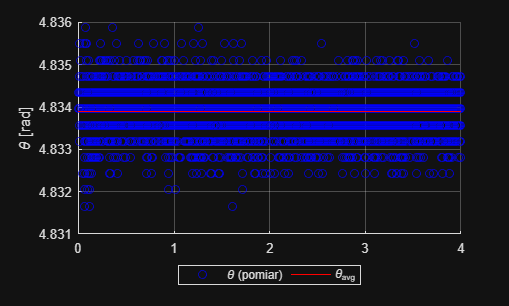


plot(theta_mech.t, mu_theta * ones(size(theta_mech.t)), 'r', ...
     'DisplayName', '\theta_{avg}');

legend('Location','southoutside','Orientation','horizontal');

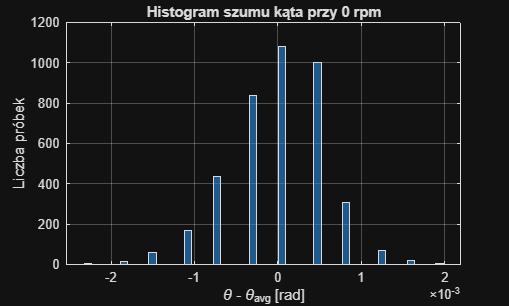


% Histogram odchyleń
theta_err = theta_vals - mu_theta;

figure;
histogram(theta_err, 50);
grid on;
title('Histogram szumu kąta przy 0 rpm');
xlabel('\theta - \theta_{avg} [rad]');
ylabel('Liczba próbek');

500 rpm - std

% Pomiar przy 500 rpm, analiza szumu pomiarowego
root = "../data/encoder";
angle_noise  = readtable(fullfile(root,'encoder_500rpm.csv'));
angle_noise  = rmmissing(angle_noise);

t0 = min(angle_noise.timestamp);

angle_noise.t  = (angle_noise.timestamp  - t0) / 1000.0;

t_min = 0;
t_max = 4;

theta_mech = angle_noise(strcmp(angle_noise.variable, "monitor_data.theta_mech"), :);

theta_mech = theta_mech(theta_mech.t >= t_min & theta_mech.t <= t_max, :);

t = theta_mech.t;
theta_raw  = theta_mech.value;
theta_vals = unwrap(theta_raw);

% 1. dopasowanie prostej: theta ≈ a*t + b
p = polyfit(t, theta_vals, 1);       % p(1)=a, p(2)=b
theta_trend = polyval(p, t);         % linia trendu

% 2. reszta = szum
theta_resid = theta_vals - theta_trend;

% 3. statystyki szumu
mu_resid    = mean(theta_resid)    % powinno być ok. 0

mu_resid = -2.0890e-13

sigma_theta = std(theta_resid)

sigma_theta = 0.0072

R           = sigma_theta^2

R = 5.2212e-05

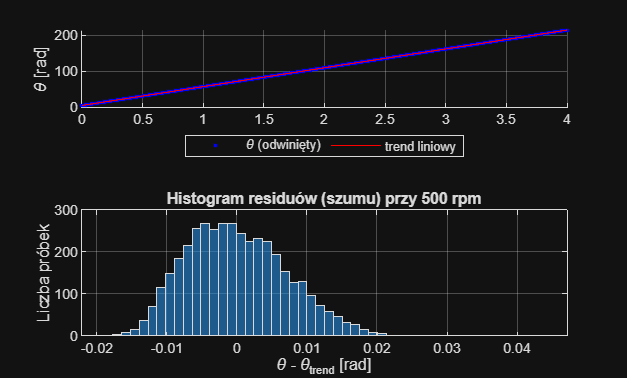


figure;
subplot(2,1,1);
hold on; grid on;
plot(t, theta_vals, 'b.', 'DisplayName','\theta (odwinięty)');
plot(t, theta_trend, 'r', 'DisplayName','trend liniowy');
ylabel('\theta [rad]');
legend('Location','southoutside','Orientation','horizontal');

subplot(2,1,2);
histogram(theta_resid, 50);
grid on;
title('Histogram residuów (szumu) przy 500 rpm');
xlabel('\theta - \theta_{trend} [rad]');
ylabel('Liczba próbek');

**KALMAN FILTER**

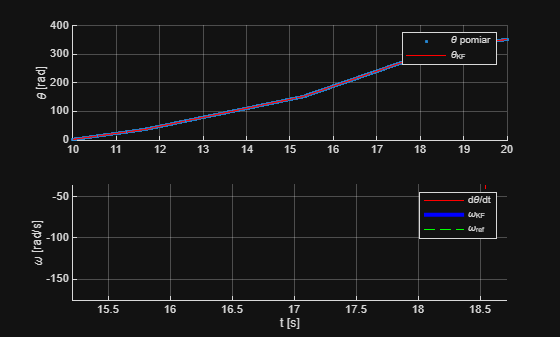

%% Kalman

% x(k) = [theta(k); w(k)] wektor stanu w chwili t

% Równania stanu:

% theta(k+1) = theta(k) + w(k)*dt
% w(k+1) = w(k)

% W formie macierzowej:
% Model stanu
% x(k+1) = A*x(k) + B*u(k) + w(k), w(k) szum procesowy (macierz kowariancji
% Q)

% Model pomiaru
% z(k) = H*x(k) + v(k), v(k) - szum pomiarowy (macierz kow. R)

root = "../data/encoder";
encoder_data  = readtable(fullfile(root,'encoder_step_response.csv'));
encoder_data  = rmmissing(encoder_data);

t0 = min(encoder_data.timestamp);

encoder_data.t  = (encoder_data.timestamp  - t0) / 1000.0;

t_min = 10;
t_max = 20;

theta_mech = encoder_data(strcmp(encoder_data.variable, "monitor_data.theta_mech"), :);
theta_mech = theta_mech(theta_mech.t >= t_min & theta_mech.t <= t_max, :);

theta_raw = theta_mech.value; % kąt modulo 2pi
theta_vals = unwrap(theta_raw); % kąt odwinięty

omega_ref = encoder_data(strcmp(encoder_data.variable, "monitor_data.speed_ref"), :);
omega_ref = omega_ref(omega_ref.t >= t_min & omega_ref.t <= t_max, :);
omega_ref_vals = omega_ref.value;           % [rpm]
omega_ref_rad  = omega_ref_vals * 2*pi/60;  % [rad/s]

t = theta_mech.t;

dt = t(2) - t(1);
x = [theta_vals(1); 0];  % Inicjalizacja wektora stanu z średnim kątem i zerową prędkością

P = eye(2);  % Macierz kowariancji stanu
A = [1, dt; 0, 1];
H = [1, 0];
R = [R];

q_theta = 1e-7;
q_omega = 1e-2;   % lub nawet 1e-1 na początek

Q = diag([q_theta, q_omega]);

N = length(theta_vals);
x_hist = zeros(2, N);   % do zapisu wyników

for k = 1:N
    % --- PREDYKCJA ---
    x = A * x;             % x(k|k-1)
    P = A * P * A' + Q;    % P(k|k-1)

    % --- KOREKCJA ---
    z = theta_vals(k);         % pomiar kąta
    y = z - H * x;             % innowacja

    S = H * P * H' + R;        % skalar
    K = P * H' / S;            % 2x1

    x = x + K * y;             % x(k|k)
    P = (eye(2) - K * H) * P;  % P(k|k)

    x_hist(:,k) = x;           % zapisz estymaty
end

theta_hat = x_hist(1,:).';   % Nx1
omega_hat = x_hist(2,:).';   % Nx1

%% Zwykłe różniczkowanie
omega_diff = diff(theta_vals) / dt;      % (N-1)x1
omega_diff = [omega_diff; omega_diff(end)];  % Nx1
t_omega    = t;                          % Nx1

%%
figure;
subplot(2,1,1);
hold on; grid on;
plot(t, theta_vals, '.', 'DisplayName','\theta pomiar');
plot(t, theta_hat, 'r', 'DisplayName','\theta_{KF}');
ylabel('\theta [rad]');
legend;

subplot(2,1,2);
hold on; grid on;
plot(t_omega, omega_diff, '-r', 'DisplayName','d\theta/dt');
plot(t,       omega_hat,  'b','LineWidth',3,'DisplayName','\omega_{KF}');
plot(omega_ref.t, omega_ref_rad, 'g--', 'DisplayName','\omega_{ref}'); % jeśli chcesz
ylabel('\omega [rad/s]');
xlabel('t [s]');
legend;

err_kf   = omega_hat  - omega_ref_rad;   % Nx1
err_diff = omega_diff - omega_ref_rad;   % Nx1

rmse_kf   = sqrt(mean(err_kf.^2)) % [rad/s]

rmse_kf = 1.5562

rmse_diff = sqrt(mean(err_diff.^2)) % [rad/s]

rmse_diff = 5.4828